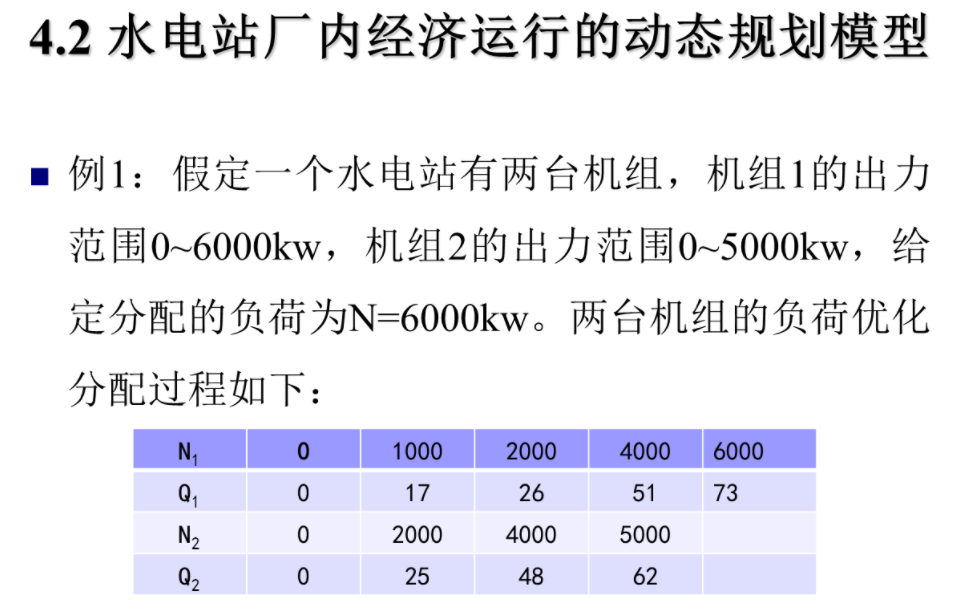

clc;clear
N_Q=[0 17 26 inf 51 inf 73
    0 inf 25 inf 48 62 inf];
[row,col]=size(N_Q);
% x_max=6000;
N=6000;
step_size=1000;
stage=row;

choose=strings(row*2,col);
choose(1,:)=N_Q(1,:);
choose(2,:)=0:step_size:N;
count=3;

f=N_Q(1,:);
for i=2:stage
    f_next=zeros(col,1);
    for x=N:-step_size:0
        storage=zeros(x/step_size+1,1);
        for y=0:step_size:x
            storage(y/step_size+1)=N_Q(i,y/step_size+1)+f((x-y)/step_size+1);
        end

        temp_max=min(storage);
        temp_num=find(storage==temp_max)';
        choose(count,x/step_size+1)=num2str(temp_max);
        choose(count+1,x/step_size+1)=num2str((temp_num-1)*step_size);
        f_next(x/step_size+1)=temp_max;
    end
    count=count+2;
    f=f_next;
end
result_value=str2double(choose(row*2-1,col))

result_value = 73

MYFUN(N,step_size,row*2,col,choose);

road = 0

road = 6000